EE583 HW1

Eda Özkaynar - 2375582

**Question 1**

load fisheriris
X = meas(:,1:2);
y = categorical(species);
labels = categories(y);

Visualize the data

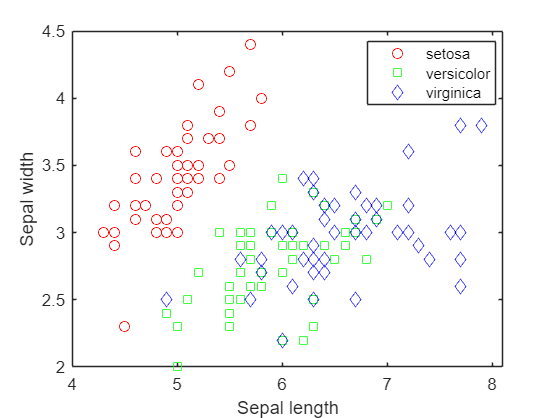

gscatter(X(:,1),X(:,2),species,'rgb','osd');
xlabel('Sepal length');
ylabel('Sepal width');

Classifiers

classifier_name = {'Naive Bayes','Discriminant Analysis','Classification Tree','Nearest Neighbor'};
classifier{1} = fitcnb(X,y);
classifier{2} = fitcdiscr(X,y);
classifier{3} = fitctree(X,y);
classifier{4} = fitcknn(X,y);

Predict and Plot

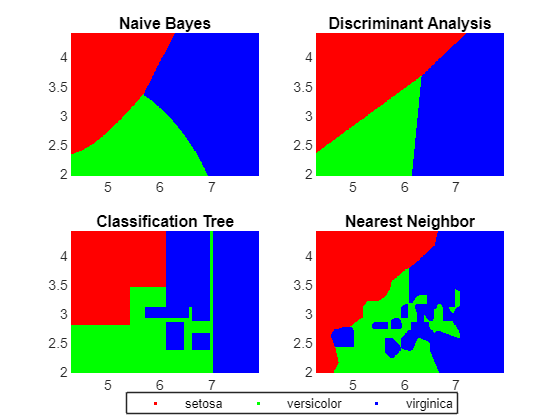

x1range = min(X(:,1)):.01:max(X(:,1));
x2range = min(X(:,2)):.01:max(X(:,2));
[xx1, xx2] = meshgrid(x1range,x2range);
XGrid = [xx1(:) xx2(:)];
for i = 1:numel(classifier)
   predictedspecies = predict(classifier{i},XGrid);

   subplot(2,2,i);
   gscatter(xx1(:), xx2(:), predictedspecies,'rgb');

   title(classifier_name{i})
   legend off, axis tight
end

legend(labels,'Location',[0.35,0.01,0.35,0.05],'Orientation','Horizontal')

**Question 2**

load fisheriris
X = meas(:,1:2);
Y = species;
labels = unique(Y);

Train a naive Bayes classifier.

mdl = fitcnb(X,Y);

Change Prior

mdl.Prior = [0.2 0.1 0.7]

mdl =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: {'setosa'  'versicolor'  'virginica'}
            ScoreTransform: 'none'
           NumObservations: 150
         DistributionNames: {'normal'  'normal'}
    DistributionParameters: {3×2 cell}


  Properties, Methods


[xx1, xx2] = meshgrid(4:.01:8,2:.01:4.5);
XGrid = [xx1(:) xx2(:)];

Prediction

[predictedspecies,Posterior,~] = predict(mdl,XGrid);

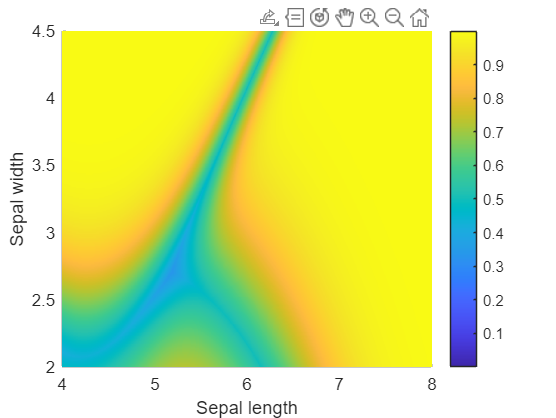

sz = size(xx1);
s = max(Posterior,[],2);

figure
hold on
surf(xx1,xx2,reshape(Posterior(:,1),sz),'EdgeColor','none')
surf(xx1,xx2,reshape(Posterior(:,2),sz),'EdgeColor','none')
surf(xx1,xx2,reshape(Posterior(:,3),sz),'EdgeColor','none')
xlabel('Sepal length');
ylabel('Sepal width');
colorbar
view(2) 
hold off

Prediction

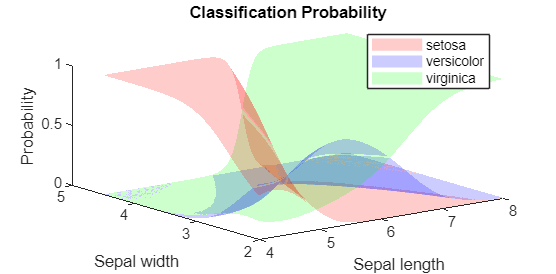

[predictedspecies,Posterior,~] = predict(mdl,XGrid);

figure('Units','Normalized','Position',[0.25,0.55,0.4,0.35]);
hold on
surf(xx1,xx2,reshape(Posterior(:,1),sz),'FaceColor','red','EdgeColor','none')
surf(xx1,xx2,reshape(Posterior(:,2),sz),'FaceColor','blue','EdgeColor','none')
surf(xx1,xx2,reshape(Posterior(:,3),sz),'FaceColor','green','EdgeColor','none')
xlabel('Sepal length');
ylabel('Sepal width');
zlabel('Probability');
legend(labels)
title('Classification Probability')
alpha(0.2)
view(3)
hold off